# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 임진빈    **

**학번**** : 201918212**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

xn = [1,2,2,1]; 
N = length(xn);
n = 0:1:N-1;
k = 0:1:N-1;
WN = exp(-j*2*pi/N);
nk = n'* k;
WNnk = WN.^nk;
Xk = xn * WNnk  %dft

Xk =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i


N1 = length(Xk);
WN1 = exp(-j*2*pi/N1);
WNnk1 = WN1.^(-nk);
xn1 = (Xk * WNnk1)/N1 %idft 기존 xn과 동일하게 나옴

xn1 =    1.0000 - 0.0000i   2.0000 - 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


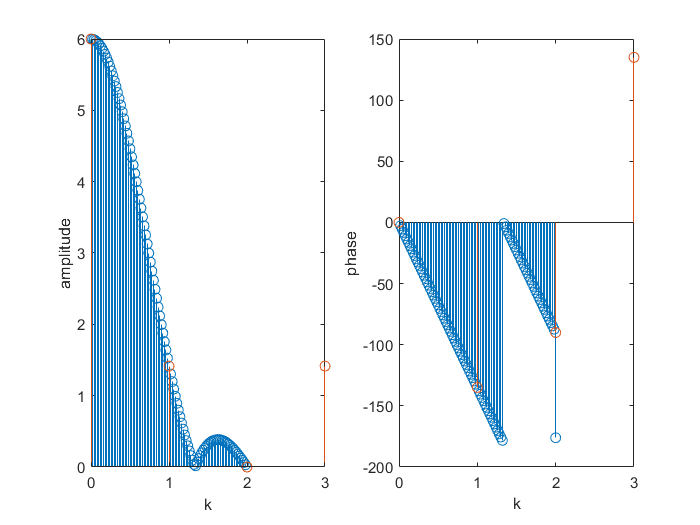

amplitude = abs(Xk); 
phase = angle(Xk)*180/pi;%%dft의 크기와 위상
k1 = 0:1:100;
w = (pi/100)*k1;
X = xn*(exp(-j*pi/100)).^(n'*k1); %dtft
amplitude1 = abs(X); 
phase1 = angle(X)*180/pi; %dtft의 크기와 위상
dw = (2*pi)/N;
figure(1), subplot(1,2,1)
stem(w/dw, amplitude1);
hold on;
stem(k, amplitude);
xlabel('k')
ylabel('amplitude');
subplot(1,2,2);
stem(w/dw, phase1);
hold on;
stem(k, phase);
xlabel('k');
ylabel('phase');

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

xn2 = [1,2,2,1,0,0,0,0,0,0,0,0,0,0,0,0]; 
N2 = length(xn2);
n2 = 0:1:N2-1;
k2 = 0:1:N2-1;
WN2 = exp(-j*2*pi/N2);
nk2 = n2'* k2;
WNnk2 = WN2.^nk2;
Xk2 = xn2 * WNnk2  %dft

Xk2 =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i


N3 = length(Xk2);
WN3 = exp(-j*2*pi/N3);
WNnk3 = WN3.^(-nk2);
xn1 = (Xk2 * WNnk3)/N3 %idft 기존 xn과 동일하게 나옴

xn1 =    1.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 - 0.0000i   1.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xn = [4,1,-1,1];
N = 4;
n = [0:1:N-1]; k =[0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'* k;
WNnk = WN.^nk;
Xk = xn * WNnk

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

xn = [1,0,-1,-1,0];
N = 5;
n = [0:1:N-1]; k =[0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'* k;
WNnk = WN.^nk;
Xk = xn * WNnk

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

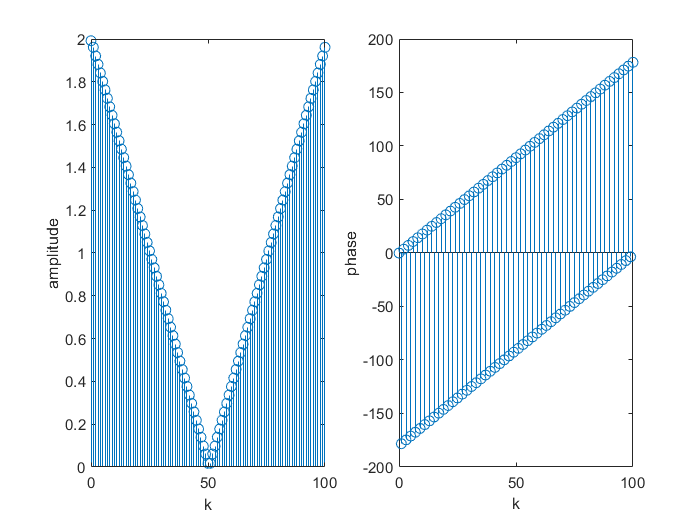

n = 0:100;
k = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
WN = exp(-j*2*pi/N);
nk = n'* k;
WNnk = WN.^nk;
Xk = xn * WNnk;
amplitude = abs(Xk); 
phase = angle(Xk)*180/pi;
figure(2), subplot(1,2,1)
stem(k, amplitude);
xlabel('k')
ylabel('amplitude');
subplot(1,2,2);
stem(k, phase);
xlabel('k');
ylabel('phase');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

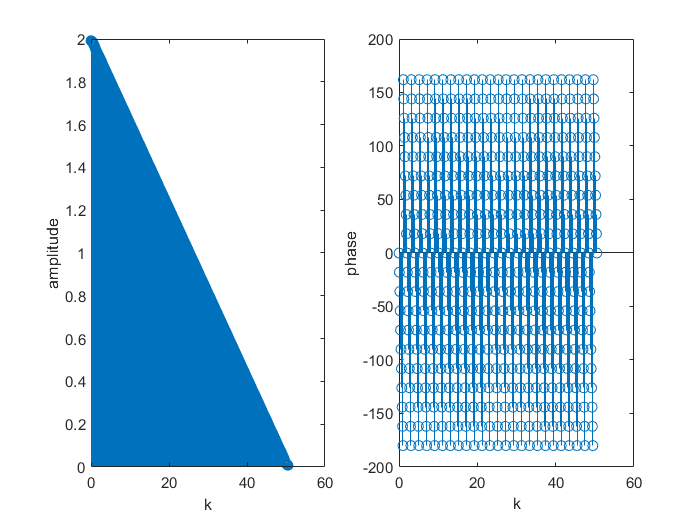

xn = sinc((n-50)/2).^2;
N = length(xn);
n = 0:1:N-1;
k1 = 0:1:500;
w = (pi/500)*k1;
X = xn*(exp(-j*pi/500)).^(n'*k1);
amplitude1 = abs(X); 
phase1 = angle(X)*180/pi;
dw = (2*pi)/N;
figure(3), subplot(1,2,1)
stem(w/dw, amplitude1);
xlabel('k')
ylabel('amplitude');
subplot(1,2,2);
stem(w/dw, phase1);
xlabel('k');
ylabel('phase');

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

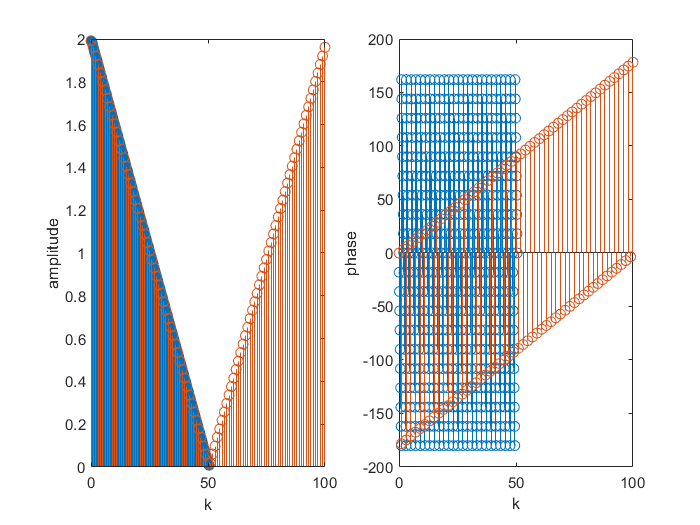

figure(4), subplot(1,2,1)
stem(w/dw, amplitude1);
hold on;
stem(k, amplitude);
xlabel('k')
ylabel('amplitude');
subplot(1,2,2);
stem(w/dw, phase1);
hold on;
stem(k, phase);
xlabel('k');
ylabel('phase');

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.